# NN Recommendation System of Books - Using User and Book Title/Description Embeddings

Imola Fodor, Information Retrieval 2023

Developed in R2023a.

## Ingest Data

The data is collected from Books Dataset at Kaggle (https://www.kaggle.com/datasets/saurabhbagchi/books-dataset) and from Goodreads found at [https://github.com/sdhilip200/Content-Based-Recommendation---Good-Reads-data](https://github.com/sdhilip200/Content-Based-Recommendation---Good-Reads-data) . The Kaggle set is taken to get mapping of book titles from user to rankings and from Goodreads to get book descriptions, for richer embeddings.

clear all
warning('off','all')

descr = readtable('data\book_decr_goodreads_sdhilip200.csv');
ids_books = readtable('data\kaggle_Books.csv');
descr.Properties.VariableNames

ans = 1×8 cell array
    {'Var1'}    {'Desc'}    {'Unnamed_0'}    {'author'}    {'genre'}    {'image_link'}    {'rating'}    {'title'}


ids_books.Properties.VariableNames

ans = 1×8 cell array
    {'ISBN'}    {'title'}    {'Book_Author'}    {'Year_Of_Publication'}    {'Publisher'}    {'Image_URL_S'}    {'Image_URL_M'}    {'Image_URL_L'}


% First hand pre-processing
descr.title = lower(descr.title);
head(descr,3)

    Var1                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                    Desc                                      

ids_books.title = lower(ids_books.title);
head(ids_books,3)

       ISBN                title                    Book_Author           Year_Of_Publication             Publisher                                       Image_URL_S                                                         Image_URL_M                                                         Image_URL_L                           
    __________    ________________________    ________________________    ___________________    ___________________________    ________________________________________________________________    ________________________________________________________________    ________________________________________________________________

    1.9515e+08    {'classical mythology' }    {'Mark P. O. Morford'  

### Basic Cleaning and Joining data

% Before joining tables, keeping unique pairs in descr table
[~,uidx] = unique(descr(:,8),'stable');
descr_without_dup = descr(uidx,:);

% Keeping only books that have descriptions in the Goodreads set
books = innerjoin(ids_books, descr_without_dup);

users_all = readtable('data\kaggle_Users.csv');
ratings_all = readtable('data\kaggle_Ratings.csv');

users_all.Properties.VariableNames

ans = 1×5 cell array
    {'User_ID'}    {'City'}    {'State'}    {'Country'}    {'Age'}


ratings_all.Properties.VariableNames

ans = 1×3 cell array
    {'User_ID'}    {'ISBN'}    {'Book_Rating'}


Originally the users.csv from Kaggle has one column Location with comma separated text for city, county, country. Text to Columns for Location and Cleaning for Country  has been done in Excel manually.

% Any User for which the Country was eliminated, gets to be removed from
% the set.
users = rmmissing(users_all);

ratings_all = innerjoin(users, ratings_all);
ratings = rmmissing(ratings_all);

### Final Join of 4 datasets

data =  innerjoin(ratings, books);

## EDA and more cleaning

size(unique(data.User_ID),1)

ans = 11885

size(unique(data.ISBN),1)

ans = 2455

size(unique(data.title),1)

ans = 792

% Same title has more ISBN, hence a unique BookID column is created to
% substitute ISBN
data.BookID = grp2idx(data.title);
size(unique(data.BookID),1)

ans = 792

data.ISBN = [];
data.Unnamed_0 = [];

columns = data.Properties.VariableNames;
data = renamevars(data,["Book_Rating","rating"],["User_Rating","Overall_Rating"]);

min(data.Overall_Rating)

ans = 3.0800

max(data.Overall_Rating)

ans = 4.5700

The Overall Rating is renamed from rating, to get distinguished from the user rating. The range of this rating is small, hence it is considered to exclude from feature set.

unique(data.genre)

ans = 2×1 cell array
    {'Business'   }
    {'Non-Fiction'}


Only Business and Non-Fuction categories, even though by personal inspection of title, Fiction is indeed present.

unique(data.author)

ans = 485×1 cell array
    {'A.A. Milne'            }
    {'A.S. Byatt'            }
    {'Aesop'                 }
    {'Agatha Christie'       }
    {'Akio Morita'           }
    {'Al Ries'               }
    {'Alan Lightman'         }
    {'Alan Moore'            }
    {'Albert Camus'          }
    {'Aldous Huxley'         }
    {'Aleksandr Solzhenitsyn'}
    {'Alex Garland'          }
    {'Alexander McCall Smith'}
    {'Alexandre Dumas'       }
    {'Alice Hoffman'         }
    {'Alice Sebold'          }
    {'Alice Walker'          }
    {'Amy Tan'               }
    {'Andre Dubus III'       }
    {'Andrew S. Grove'       }
    {'Anita Diamant'         }
    {'Anita Shreve'          }
    {'Ann Brashares'         }
    {'Ann Patchett'          }
    {'Anna Sewell'           }
    {'Anne Rice'             }
    {'Anne Tyler'            }
    {'Annie Proulx'          }
    {'Anonymous'             }
    {'Anthony Burgess'       }


size(unique(data.User_ID),1)

ans = 11885

min(data.User_Rating)

ans = 0

max(data.User_Rating)

ans = 10

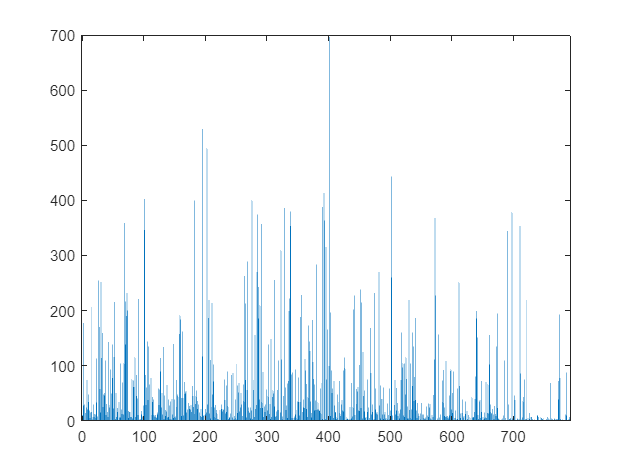

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: 'none'
    BaseValue: 0
        XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 81 … ]
        YData: [11 177 28 29 2 14 24 74 21 34 48 19 5 15 16 207 2 7 30 12 6 11 33 113 8 1 255 170 58 15 252 114 159 25 48 46 51 109 11 31 16 7 143 29 24 93 2 50 77 139 22 116 216 3 50 7 23 16 1 34 6 6 104 20 12 70 11 104 359 216 139 190 232 200 5 18 … ]

  Show all properties


G = groupsummary(data,"BookID");
b = bar(G.BookID, G.GroupCount)

The User Rating is more promising as a feature. For the use-case, only higher ratings are considered, since we are modelling what the user likes.

Also, we exclude users who read less than 15 books.

% Keep only good ratings
data(find(data.User_Rating <5), :) = [];

% Keep only users who read at least 15 books
data = groupfilter(data,"User_ID",@(x) numel(x) > 14);

## Feature Engineering

data.Age_Bin = zeros(size(data,1),1);
data.Age_Bin(find(data.Age<=18),:) = 1;
data.Age_Bin(find(data.Age>18 & data.Age<=36),:) = 2;
data.Age_Bin(find(data.Age>36 & data.Age<=55),:) = 3;
data.Age_Bin(find(data.Age>55),:) = 4;

### Feature Selection

nndata = data(:, ["User_ID", "Age_Bin","Country", "User_Rating", "BookID", "title","Year_Of_Publication","Desc"]);

## Separate Train/Test Data - 3 books per User set aside

% Manual separation in Excel choosing 3 ratings per user for test

nndataXRaw = readtable('nndataTrainRawText.csv');
nndataYRaw = readtable('nndataTestRawText.csv');

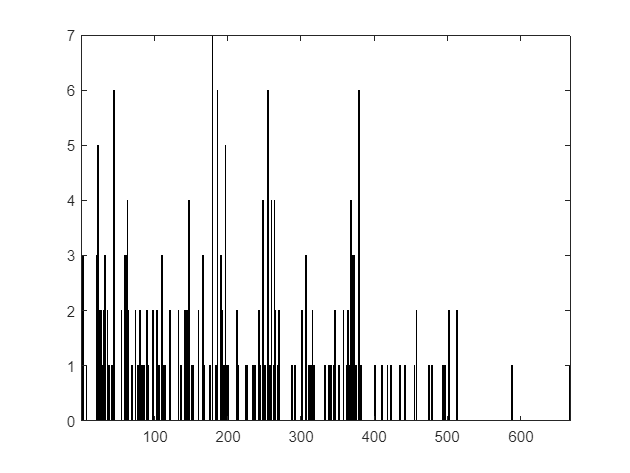

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [2 7 21 23 24 25 27 30 31 32 33 36 37 38 42 44 45 55 60 62 63 64 69 74 77 79 80 83 86 90 91 98 103 106 110 112 113 114 121 133 136 142 143 144 145 147 151 152 153 160 166 167 168 176 179 183 184 186 191 193 195 197 198 200 212 213 214 … ]
        YData: [3 1 3 5 2 1 2 1 2 3 2 2 1 1 1 2 6 2 3 3 4 2 1 2 1 1 2 1 1 2 1 2 2 1 3 1 1 1 2 2 1 2 1 2 1 4 1 1 1 2 3 1 1 1 7 1 1 6 3 2 1 5 1 1 1 2 1 1 1 1 1 1 1 2 1 4 1 1 6 1 4 1 4 2 1 2 1 1 2 1 3 1 1 1 1 1 2 1 1 1 1 1 1 1 2 2 1 1 2 1 2 1 4 3 3 3 1 … ]

  Show all properties


G = groupsummary(nndataYRaw,"BookID");
b = bar(G.BookID, G.GroupCount)

## Custom Word Embedding using Titles

% Prepare dataset for custom word2vec
desc_joined_str = strjoin(string(nndataXRaw.title));

textData = split(desc_joined_str,newline);
documents = tokenizedDocument(textData);

% Some house-keeping
documents = erasePunctuation(documents);
documents= removeStopWords(documents);

% No custom hyperparameter chosen, skipgram approach by default
emb = trainWordEmbedding(documents)

Training: 100% Loss: 3.73587  Remaining time: 0 hours 0 minutes.


emb =   wordEmbedding with properties:

     Dimension: 100
    Vocabulary: ["House"    "Life"    "Kill"    "Time"    "Good"    "Red"    "Girl"    "Guide"    "Things"    "Green"    "Secret"    "Wicked"    "Brief"    "Mockingbird"    "Claiborne"    "Little"    "Dolores"    "Pelican"    "Galaxy"    …    ]


### TSNE Visual

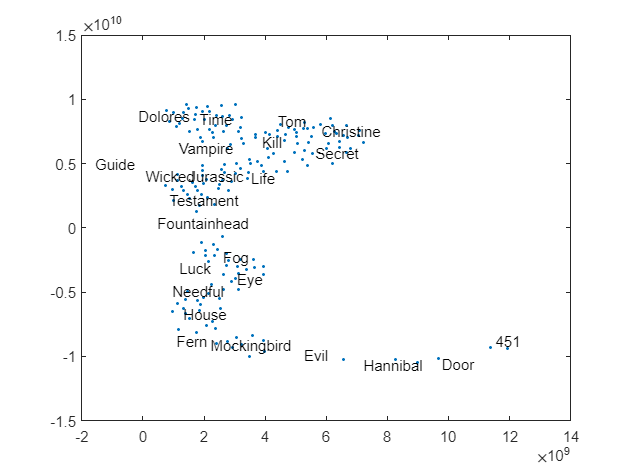

% Visualize embedding
words = emb.Vocabulary;
V = word2vec(emb, words);
XY = tsne(V);
textscatter(XY,words)

### X : Use trained embedding for first round encoding + Age feature

[G,user] = findgroups(nndataXRaw.User_ID);
anonFunc = @(optimValues, ~) avg_embedding(emb, optimValues);
[title_emb, age_bin] = splitapply(anonFunc,[nndataXRaw.title, num2cell(nndataXRaw.Age_Bin)],G);
mean_vec_title = double(title_emb);
nndataX = [user age_bin mean_vec_title];

[G,user] = findgroups(nndataYRaw.User_ID);
[bookID1, bookID2, bookID3] = splitapply(@getBooks,nndataYRaw.BookID,G);
nndataY = [user bookID1 bookID2 bookID3];

### Y: One hot encoding of output (1/3)

% One hot encoding of output
response = categorical(nndataY(:, 2));
response = onehotencode(response,2);

dsX2Train = arrayDatastore(nndataX(1:74, 2));
dsX1Train = arrayDatastore(nndataX(1:74, 3:end)', "IterationDimension",2);
dsTTrain = arrayDatastore(response(1:74,:));
dsTrain = combine(dsX1Train,dsX2Train,dsTTrain);

dsX2Val = arrayDatastore(nndataX(75:82, 2));
dsX1Val = arrayDatastore(nndataX(75:82, 3:end)', "IterationDimension",2);
dsTVal = arrayDatastore(response(75:82,:));
dsVal = combine(dsX1Val,dsX2Val,dsTVal);

## "End-to-End" Modelling

Note: Would have been a reasonable alternative, to not embed before-hand the input, but use traditional encoding. And leave the fc1 layer to act as a learnt embedding.

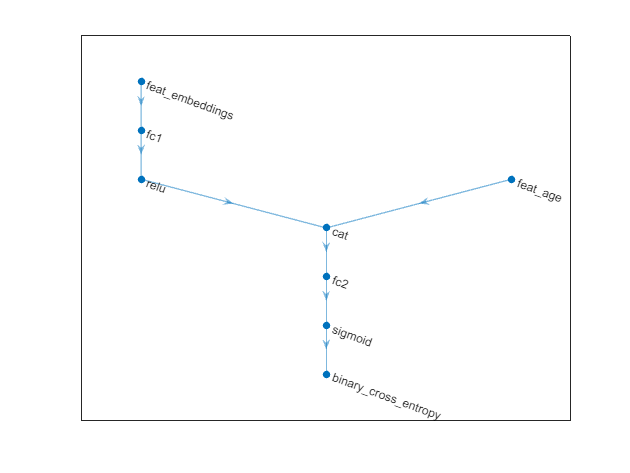

numFeatures = size(nndataX(:, 3:end),2);
% 60 different books are in the test set
numClasses = size(response, 2); 

numHiddenUnits = 100;

layers = [
    featureInputLayer(numFeatures, Name='feat_embeddings')
    fullyConnectedLayer(100, Name = 'fc1')
    reluLayer
    concatenationLayer(1,2,Name="cat")
    fullyConnectedLayer(numClasses, Name = 'fc2')
    sigmoidLayer(Name = 'sigmoid')
    CustomBinaryCrossEntropyLossLayer("binary_cross_entropy")];

lgraph = layerGraph(layers);

featInput2 = featureInputLayer(1, Name = 'feat_age');
lgraph = addLayers(lgraph,featInput2);
lgraph = connectLayers(lgraph,"feat_age","cat/in2");
plot(lgraph)

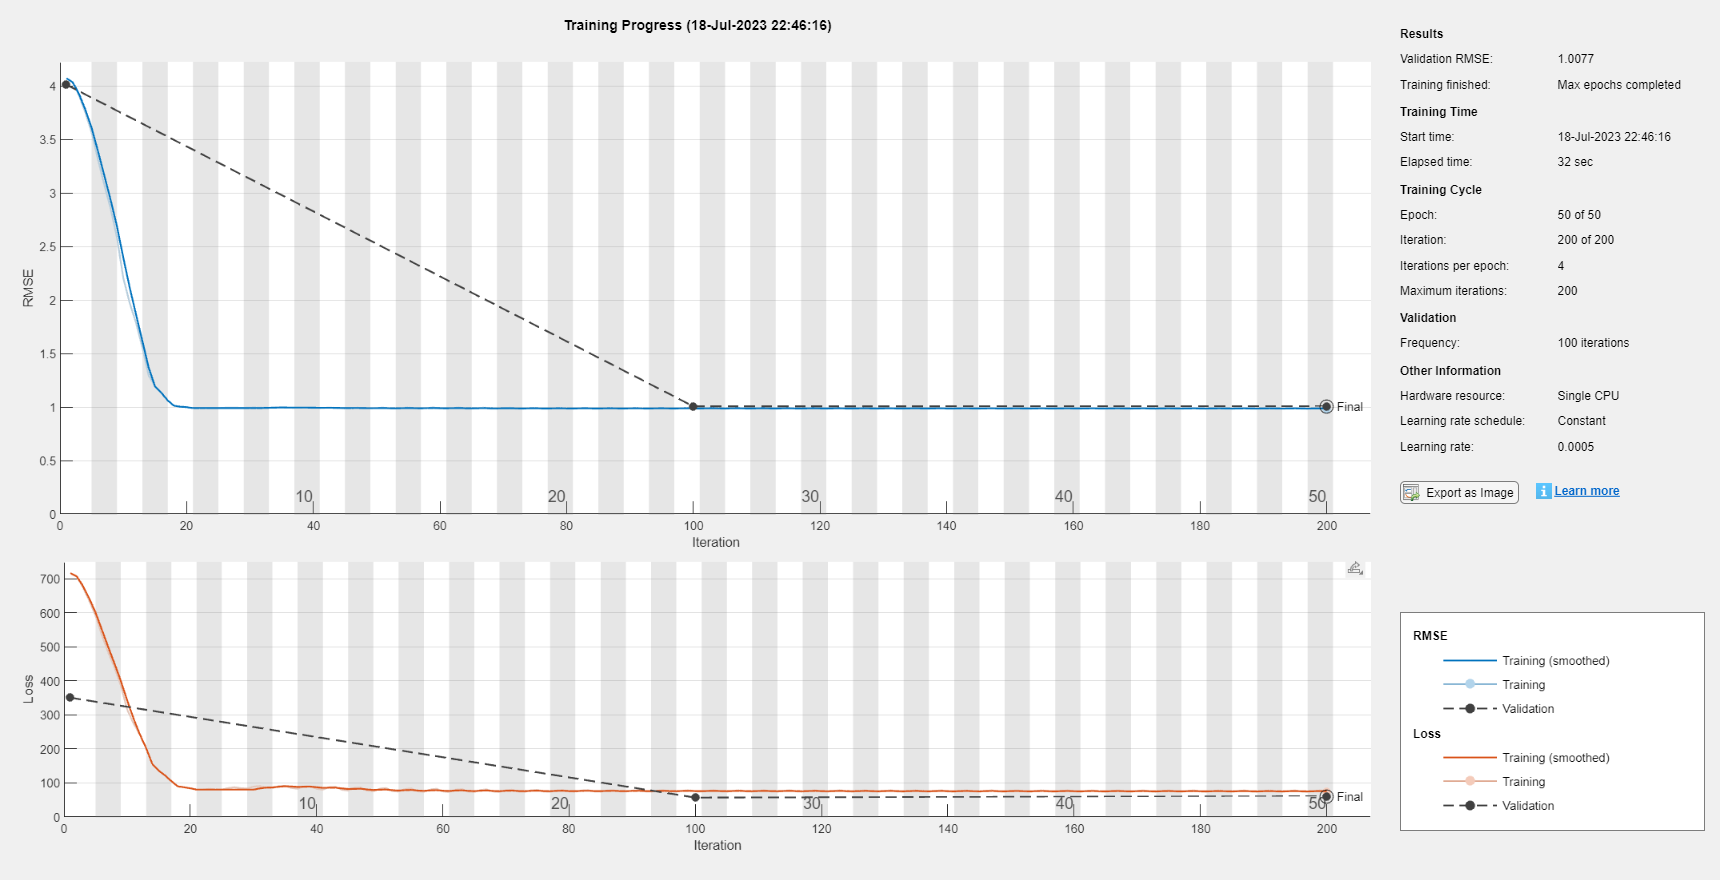

% No hyperparam tuning performed
options = trainingOptions("sgdm", ...
    InitialLearnRate=0.0005, ...
    MiniBatchSize=16, ...
    MaxEpochs=50, ...
    Verbose= false, ...
    ValidationData=dsVal, ...
    ValidationFrequency=100, ...
    ValidationPatience=5, ...
    Plots="training-progress");

trainedNet = trainNetwork(dsTrain,lgraph,options);

## (Bad) Results

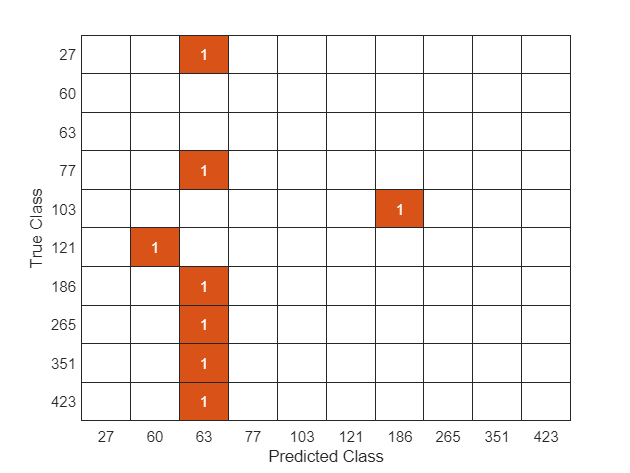

YPred = predict(trainedNet,dsVal);
bookTestID = unique(nndataY(:, 2));

[YPredTop, i] = maxk(YPred,3,2);

YPredresult = bookTestID(i);

figure
confusionchart(nndataY(75:82,2),YPredresult(:,1))

% Quite a Fictional book
title = nndata(find(nndata.BookID==255),6); title(1,1)

ans = table
           title        
    ____________________

    {'the pilot's wife'}


## Factors for improvement

- Due to lack of time, only the title and age are considered for this modelling, even though a rich set (rankings, even images) are provided in the dataset.

- Only one out of three books that were set aside per user are used in training. Much more of them can be used, creating encodings of output with multiple "1s".

Annex Data for Python nn-recommendation-system-word2vec.ipynb on github

nndata_train = [nndataX(1:75, 2:end) nndataY(1:75, 2:end)];
nndata_test = [nndataX(76:end, 2:end) nndataY(76:end, 2:end)];
    
writematrix(nndataX(1:75, 2:end), 'nndataTrainXCustomEmbTitle.csv')
writematrix(nndataY(1:75, 2:end), 'nndataTrainYCustomEmbTitle.csv')
writematrix(nndataX(76:end, 2:end), 'nndataTestXCustomEmbTitle.csv')
writematrix(nndataY(76:end, 2:end), 'nndataTestYCustomEmbTitle.csv')


## Helper Functions

As a separate file, provided by Mathworks: CustomBinaryCrossEntropyLossLayer.m

function [avg_title_emb, age_bin] = avg_embedding(emb, x, optimValues)

title_embs = [];

for i=1:size(x,1) 
    
    title = string(x(i,1)); 
    
    title = strrep(title,',','');
    title = strrep(title,'.','');
    
    splits = split(title, ' ');
    title_emb = word2vec(emb, splits);
    title_emb = rmmissing(title_emb);
    title_embs = [title_embs;title_emb];  
    
end

avg_title_emb = mean(title_embs);
age_bin = cell2mat(x(1,2));
    
end

function [id1, id2, id3] = getBooks(x)

id1 = x(1);
id2 = x(2);
id3 = x(3);
end


Inspired by [https://ceur-ws.org/Vol-2871/paper2.pdf](https://ceur-ws.org/Vol-2871/paper2.pdf)  Embedding-based Neural Network Models for Book Recommendation in University Libraries, Choi et al. 2021 